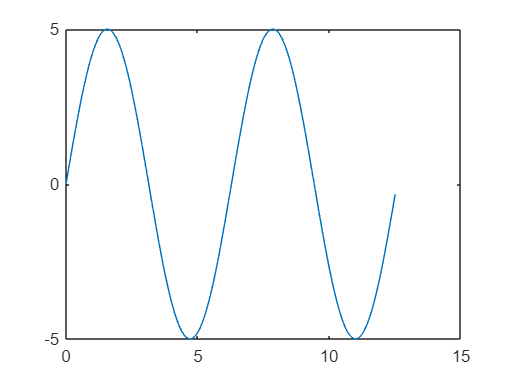

%DM 
clear all;
close all;
clc;
K=0.9;
fs=10;
f=10;
A=5;
t=0:1/fs:4*pi;
x=A*sin(t);
delta=0.3;
y=DM(x,delta);

plot(t,x);

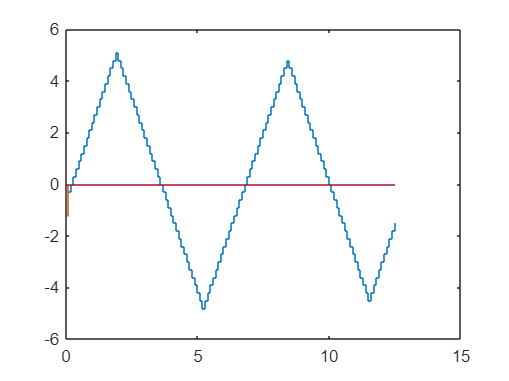

stairs(t,y);

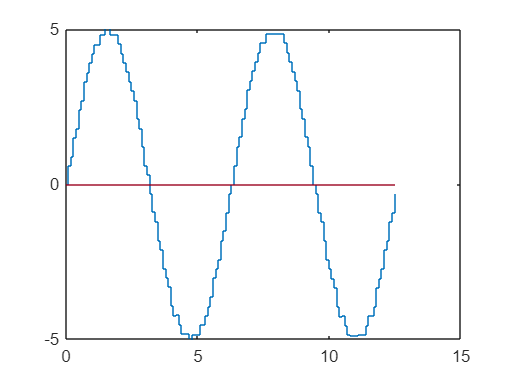



%ADM
z=ADM(x,delta,K);
stairs(t,z);
axis([0,15,-5,5])

function y=DM(x,delta)
    N=length(x);
    xn=zeros(N);
    for i=1:N
        if x(i)>xn(i)
            xn(i+1)=xn(i)+delta;
        else
            xn(i+1)=xn(i)-delta;
        end
    end
    y=xn;
end

function z=ADM(x,delta_init,K)
    delta=delta_init;
    N=length(x);
    z=zeros(N);
    e=zeros(N);
    quantize= @(x,delta) round(x/delta);
    for n=2:N
        z(n)=quantize(x(n),delta);
        e(n)=x(n)-z(n)*delta;
        z(n)=z(n)*delta;
        delta=delta*K^(e(n)*e(n-1));
        if delta<0.01
            delta=0.01;
        end
    end
end